Interface de texto para PVI

Autor:

  - Arménio Correia  .: armenioc@isec.pt

  - Ana Rita Conceição Pessoa - 2023112690 

  - João Francisco de Matos Claro - 2023112690 

Data : 13/03/2024

clear

% helper vector com cores mais faceis aos olhos
colors = [[0, 0.4470, 0.7410]; ...
    [0.8500, 0.3250, 0.0980]; ...
    [0.9290, 0.6940, 0.1250]; ...
    [0.4940, 0.1840, 0.5560]; ...
    [0.4660, 0.6740, 0.1880]; ...
    [0.3010, 0.7450, 0.9330]; ...
    [0.6350, 0.0780, 0.1840]];

strF="-sin(y)-0.3*y";
%str2func cria uma funcao utilizando a string
%strcat contactenacao de strings
f=str2func(vectorize(strcat('@(t,y)', " ", strF)));
a = 1;
b = 5;
if ~(isscalar(b) && b > a)
    disp("Introduza um b > a");
end
n = 20;
if ~(isscalar(n) && n==floor(n) && n > 0)
    disp("Introduza um valor de n correto");
end
y0 = 3.14;

%Variaveis para graficos
h = (b-a)/n;
t = a:h:b;

yValue(:,1) = t.';
methods(1) = "t";

% Alinha automaticamente os graficos consoante o numero
% de metodos na figura
tiledlayout('flow');

if(true)
    [~, y]=NEuler(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler", y, t, colors(length(methods), :));
    methods(end+1) = "Euler";
end
if(false)
    [~, y]=NEulerMelhorado(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Euler Melhorado", y, t, colors(length(methods), :));
    methods(end+1) = "Euler M";
end
if(false)
    [~, y]=RK2(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK2", y, t, colors(length(methods), :));
    methods(end+1) = "RK2";
end
if(false)
    [~, y]=RK4(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("RK4", y, t, colors(length(methods), :));
    methods(end+1) = "RK4";
end
if(true)
    [~, y]=AdamBashforth(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Adams-Bashforth", y, t, colors(length(methods), :));
    methods(end+1) = "Adams-Bashforth";
end
if(false)
    [~, y]=sExata(f,a,b,n,y0);
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("Exata", y, t, colors(length(methods), :));
    methods(end+1) = "Exata";
end
if(true)
    [~, y]=ode45(f,t,y0);
    % y da ode45 ja e vetor do tipo t linhas x 1 coluna
    %de modo a trabalhar com o vetor y igual aos outros metodos
    y = y.';
    yValue(:,length(yValue(1,:))+1) = y.';
    mostraGrafico("ode45", y, t, colors(length(methods), :));
    methods(end+1) = "ode45";
end

% mostra dados da table
data = array2table(yValue, 'VariableNames', methods);
disp(data);

     t      Euler      Adams-Bashforth     ode45  
    ___    ________    _______________    ________

      1        3.14           3.14            3.14
    1.2      2.9513         2.9513          2.9375
    1.4      2.7364         2.7233          2.7058
    1.6      2.4933         2.4638          2.4445
    1.8       2.223         2.1762          2.1581
      2      1.9307         1.8703          1.8571
    2.2      1.6276         1.5628          1.5573
    2.4      1.3303         1.2739          1.2755
    2.6      1.0562         1.0192          1.0249
    2.8     0.81876        0.80582         0.81173
      3     0.62357        0.63262         0.63658
    3.2     0.46937        0.49462         0.49601
    3.4     0.35074         0.3858         0.38488
    3.6     0.26098         0.3005         0.29792
    3.8     0.19371        0.23386         0.23

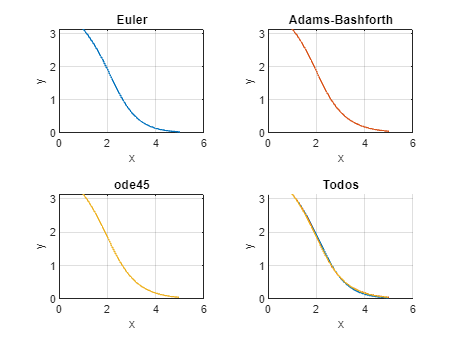


% mostrar os graficos todos juntos
mostraTodos(methods, yValue, colors);

clf reset;

function mostraGrafico(metodo, y, t, cor)
nexttile
plot (t, y, 'DisplayName', metodo, 'Color', cor);
title(metodo);
xlabel('x');
ylabel('y');
grid on
end

function mostraTodos(metodo, y, colors)
% Desenha todos num unico grafico
nexttile
title("Todos");
%t e um vetor que guarda o tamanho da matrix y
%com [linhas colunas]
t = size(y);
hold on
for i = 2:t(2)
    plot (y(:,1).', y(:, i).', 'DisplayName', metodo(i), 'Color', colors((i-1),:));
    % legend('location', 'best');
end
hold off
grid on
xlabel('x');
ylabel('y');
end
